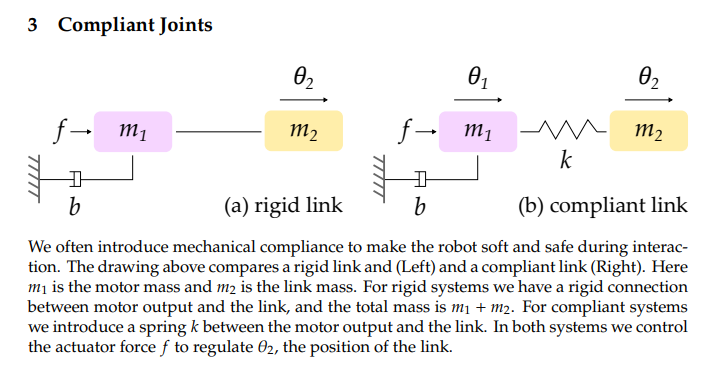

syms F s m1 m2 theta_1 theta_2 k b real

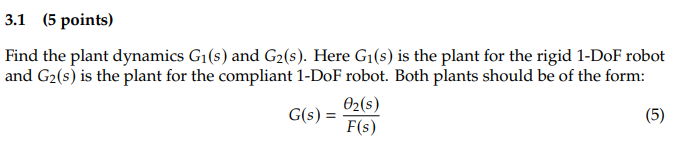

% G1 evaluation
eqn = F == (m1 + m2)*s^2*theta_2 + b*s*theta_2

$$eqn = F=\theta_{2}\,\left(m_{1}+m_{2}\right)\,s^{2}+b\,\theta_{2}\,s$$

G1 = solve(eqn, theta_2)/F

$$G1 = \frac{1}{\left(m_{1}+m_{2}\right)\,s^{2}+b\,s}$$

% G2 evaluation

eqn = F - b*s*theta_1 == m1*s^2*theta_1 + k*(theta_1 - theta_2)

$$eqn = F-b\,s\,\theta_{1}=m_{1}\,\theta_{1}\,s^{2}+k\,\left(\theta_{1}-\theta_{2}\right)$$

theta_1 = simplify(solve(eqn, theta_1))

$$theta\_1 = \frac{F+k\,\theta_{2}}{m_{1}\,s^{2}+b\,s+k}$$

eqn = -k*(theta_2 - theta_1) == m2*s^2*theta_2

$$eqn = -k\,\left(\theta_{2}-\frac{F+k\,\theta_{2}}{m_{1}\,s^{2}+b\,s+k}\right)=m_{2}\,s^{2}\,\theta_{2}$$

G2 = simplify(solve(eqn, theta_2))/F

$$G2 = \frac{k}{s\,\left(b\,k+b\,m_{2}\,s^{2}+m_{1}\,m_{2}\,s^{3}+k\,m_{1}\,s+k\,m_{2}\,s\right)}$$

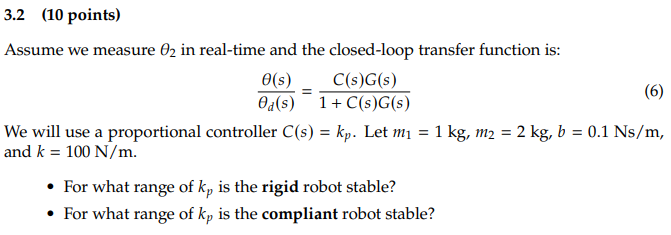

% 3.2 (a)

syms C G theta_d theta real

eqn = G*(C*(theta_d - theta)) == theta;
eqn = solve(eqn, theta)/theta_d

$$eqn = \frac{C\,G}{C\,G+1}$$

[~,den] = numden(eqn)

$$den = C\,G+1$$

syms kp real

c = kp;

g = G1;

eqn = subs(den, [C,G], [c,g]) == 0

$$eqn = \frac{\mathrm{kp}}{\left(m_{1}+m_{2}\right)\,s^{2}+b\,s}+1=0$$

eqn = simplify(subs(eqn, [m1, m2, b, k], [1, 2, 0.1, 100])) % Further range is provided in the written section, this is just to get the simplified characteristic equation with s and Kp

$$eqn = 30\,s^{2}+s+10\,\mathrm{kp}=0\wedge s\neq 0\wedge s\neq -\frac{1}{30}$$

% 3.2 (b)

c = kp;

g = G2;

eqn = subs(den, [C,G], [c,g]) == 0

$$eqn = \frac{k\,\mathrm{kp}}{s\,\left(b\,k+b\,m_{2}\,s^{2}+m_{1}\,m_{2}\,s^{3}+k\,m_{1}\,s+k\,m_{2}\,s\right)}+1=0$$

eqn = subs(eqn, [m1, m2, b, k], [1, 2, 0.1, 100]) % Further range is provided in the written section, this is just to get the simplified characteristic equation with s and Kp

$$eqn = \frac{100\,\mathrm{kp}}{s\,\left(2\,s^{3}+\frac{s^{2}}{5}+300\,s+10\right)}+1=0$$